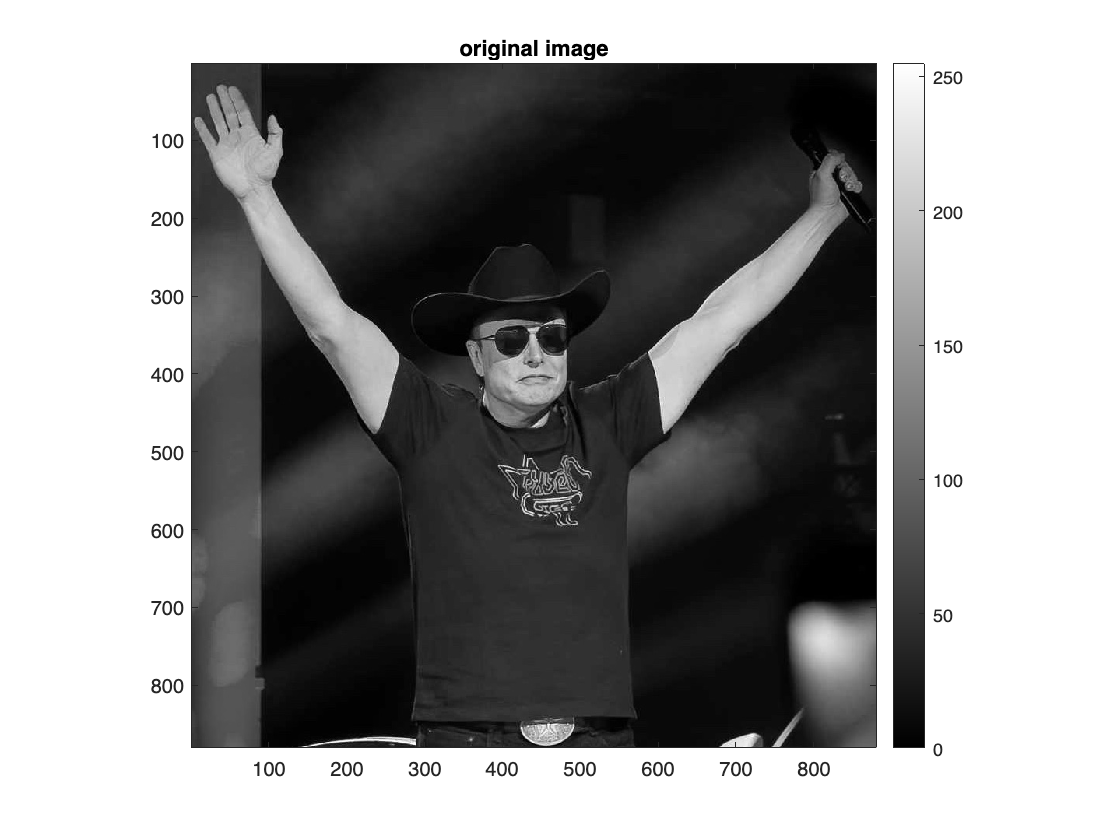

I = imread('sample_images/c1.jpg');
if size(I,3)==3
    I = rgb2gray(I);
end

figure(1); imagesc(I);title('original image'); axis('square'); colormap('gray'); colorbar;

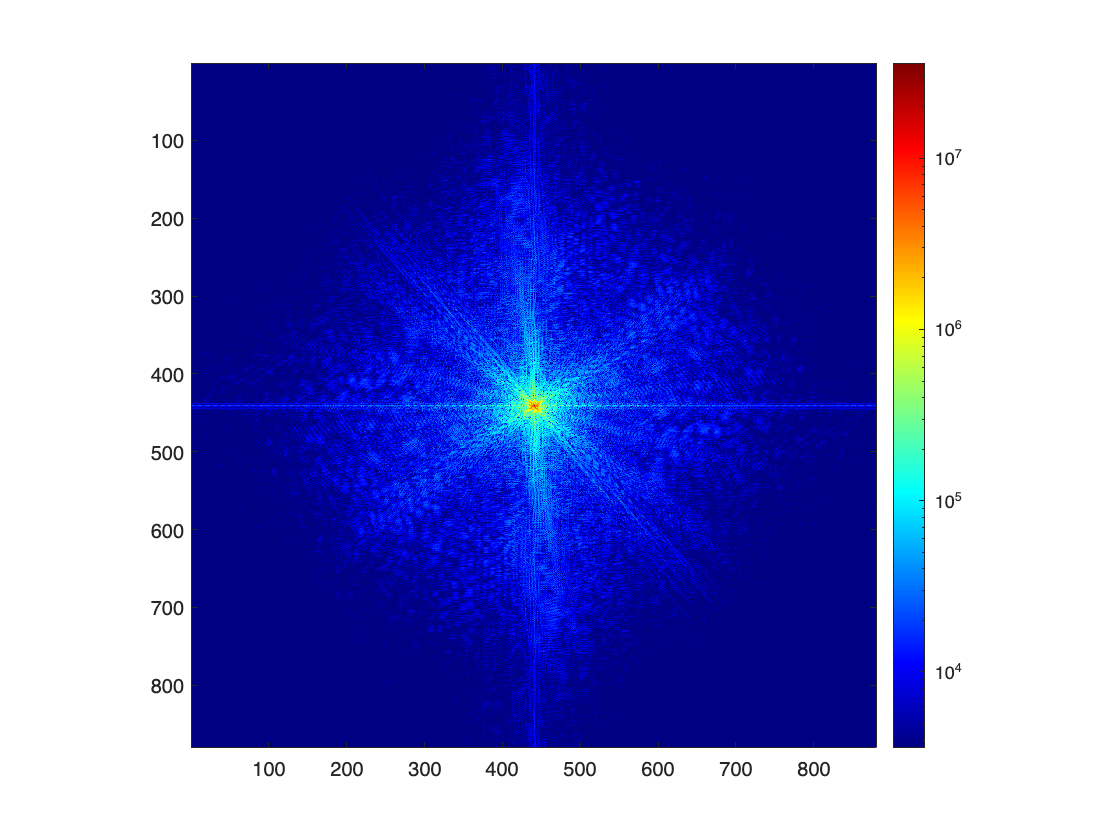

I_f = ifftshift(fft2(fftshift(I)));
figure(2); imagesc(abs(I_f)); axis('square'); colormap('jet'); colorbar; set(gca, 'ColorScale', 'log');

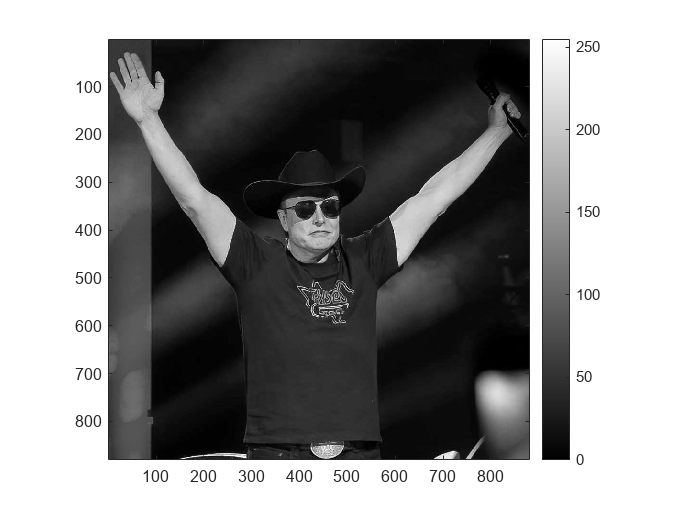

I_if = fftshift(ifft2(ifftshift(I_f)));
figure(3); imagesc(abs(I_if)); axis('square'); colormap('gray'); colorbar;

## Zero Padding

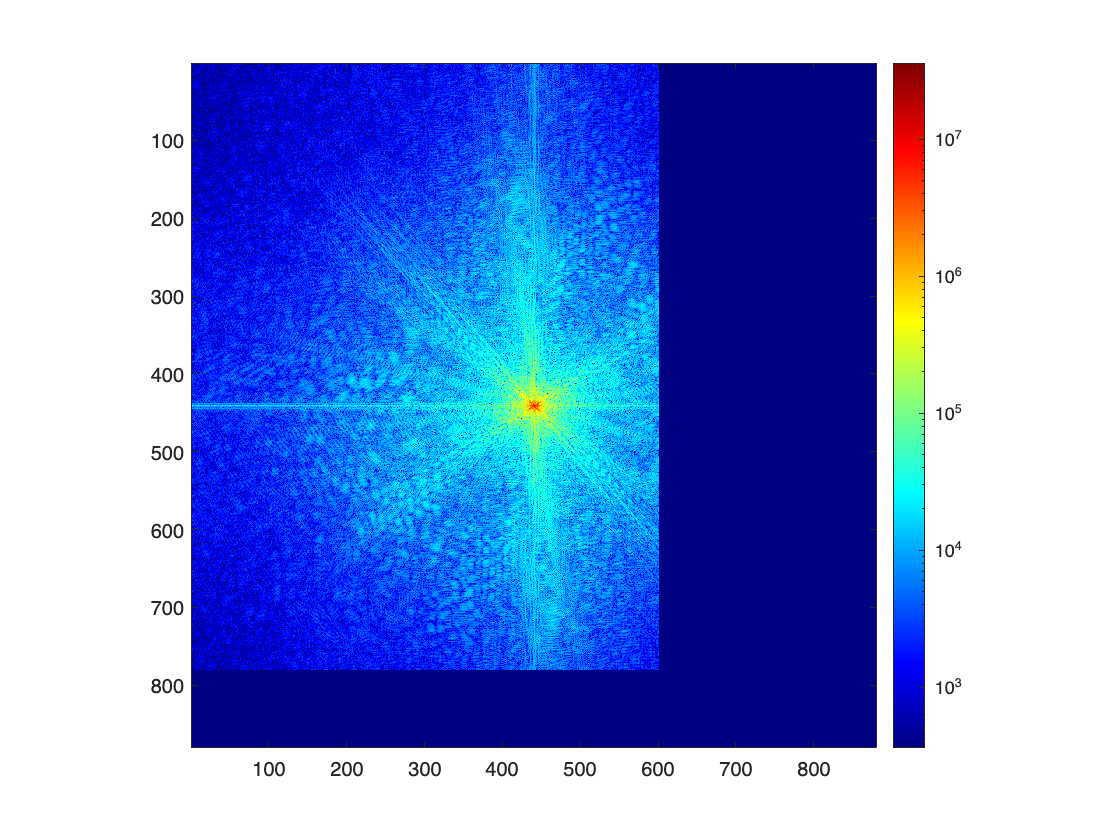

[I_if1, I_f1] = pifft_zero_padding(I_f, 1, 600, 1, 780); 
figure(4); imagesc(abs(I_f1)); axis('square'); colormap('jet'); colorbar; set(gca, 'ColorScale', 'log');

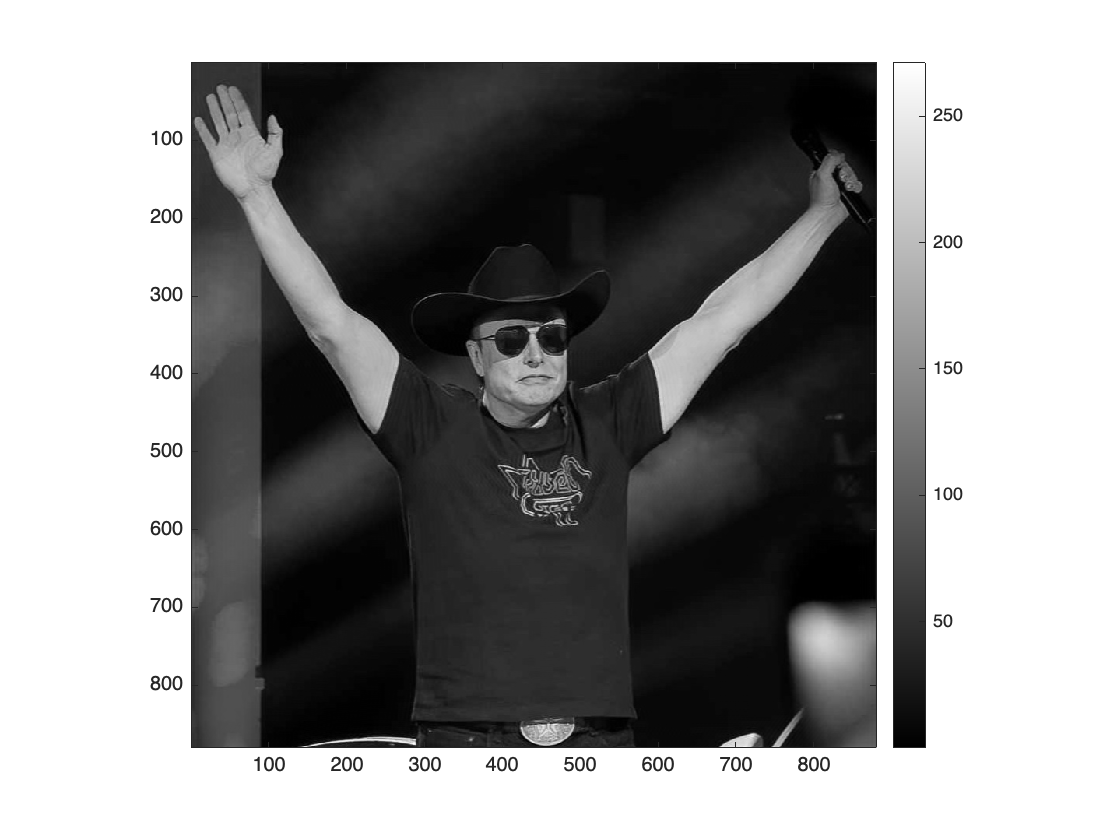

figure(5); imagesc(abs(I_if1)); axis('square'); colormap('gray'); colorbar;

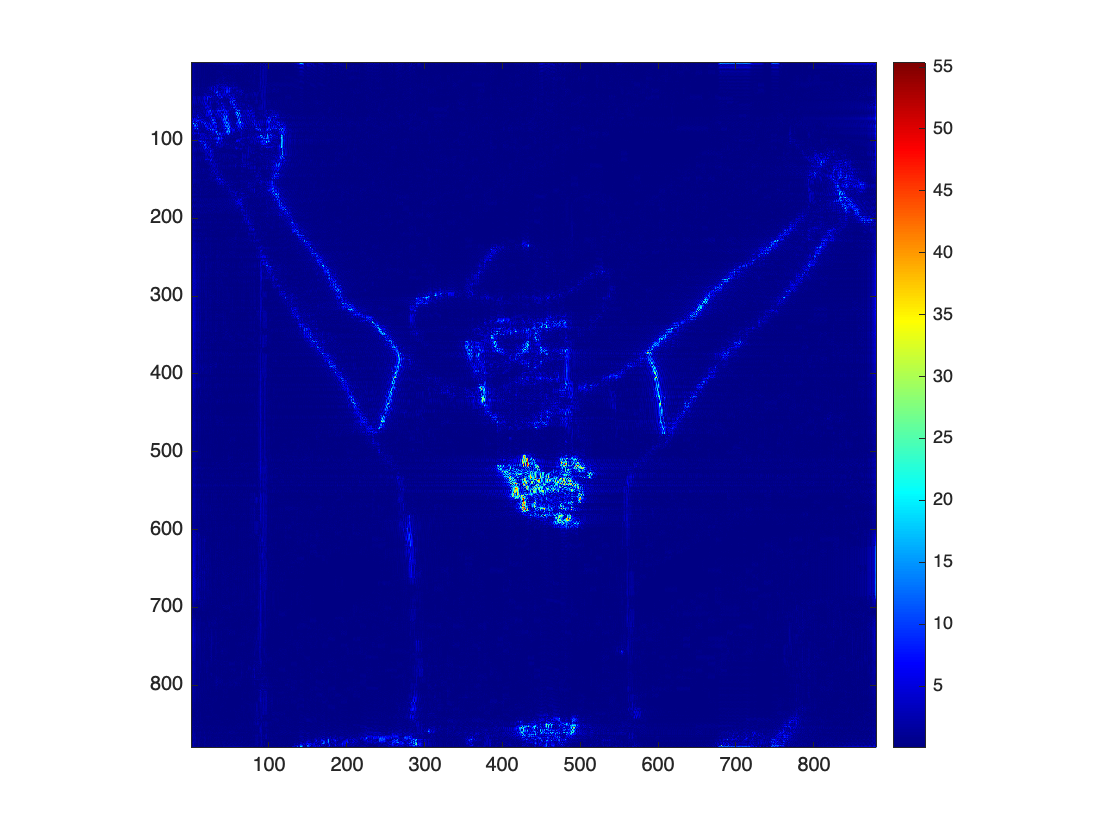

figure(6); imagesc(abs(abs(I_if1)-double(I))); axis('square'); colormap('jet'); colorbar;

disp(immse(abs(I_if1),double(I)));

    4.1189



## Phase Correction

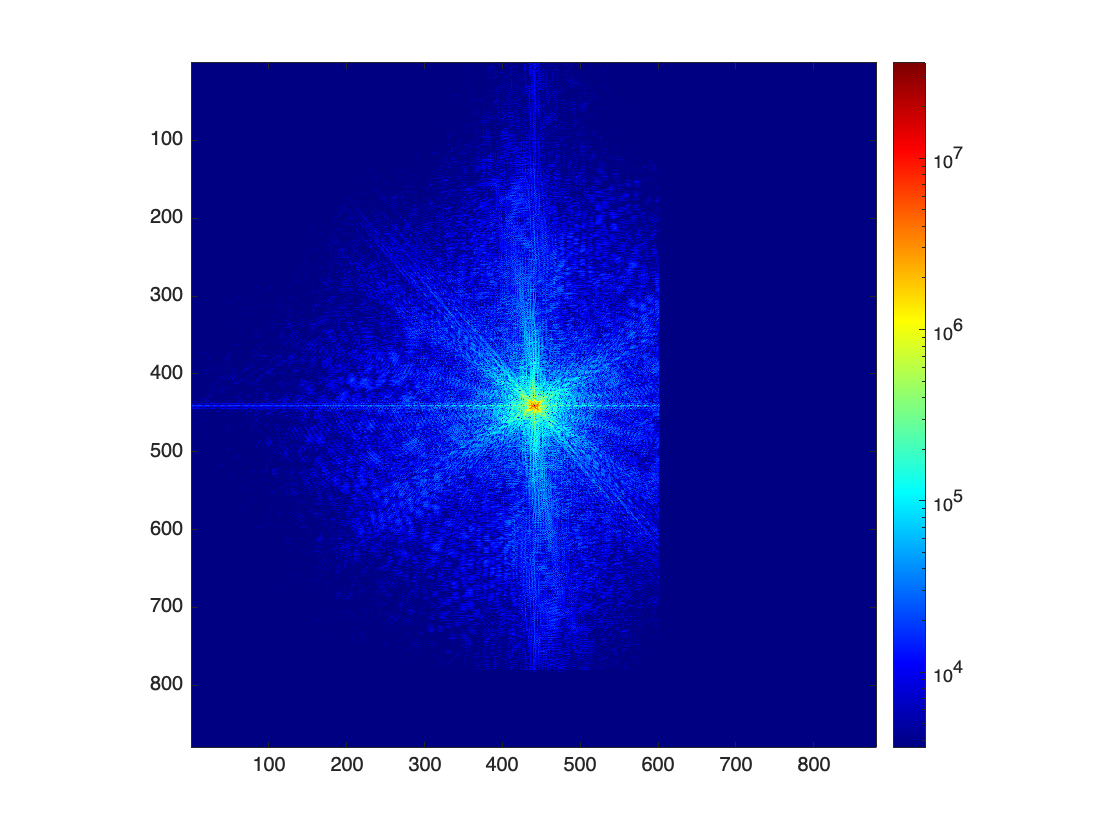

[Ip, Ipp, Ips, If_pp, If_ps] = pifft_phase_correction(I_f, 1, 600, 1, 780); 
figure(8); imagesc(abs(ifftshift(fft2(fftshift(Ip))))); axis('square'); colormap('jet'); colorbar; set(gca, 'ColorScale', 'log');

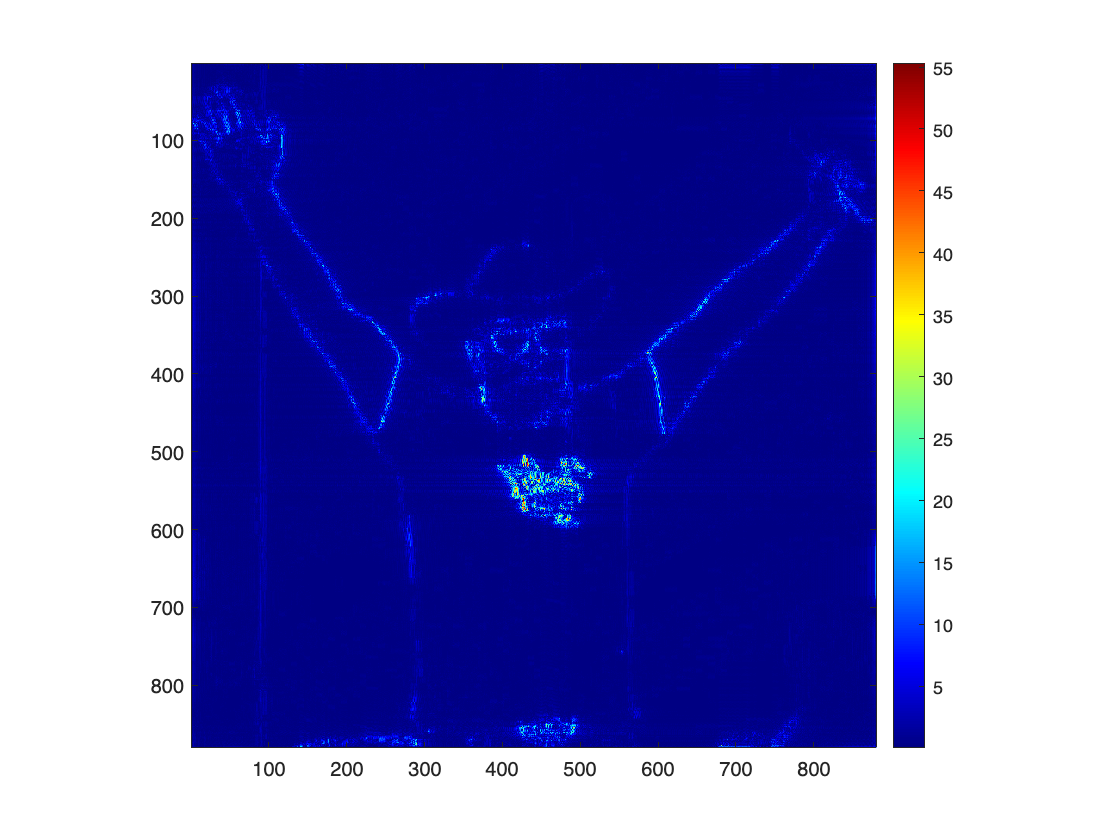

figure(7); imagesc(abs(abs(Ip)-double(I))); axis('square'); colormap('jet'); colorbar;

disp(immse(abs(Ip),double(I)));

    4.1189



## Conjugate Synthesis

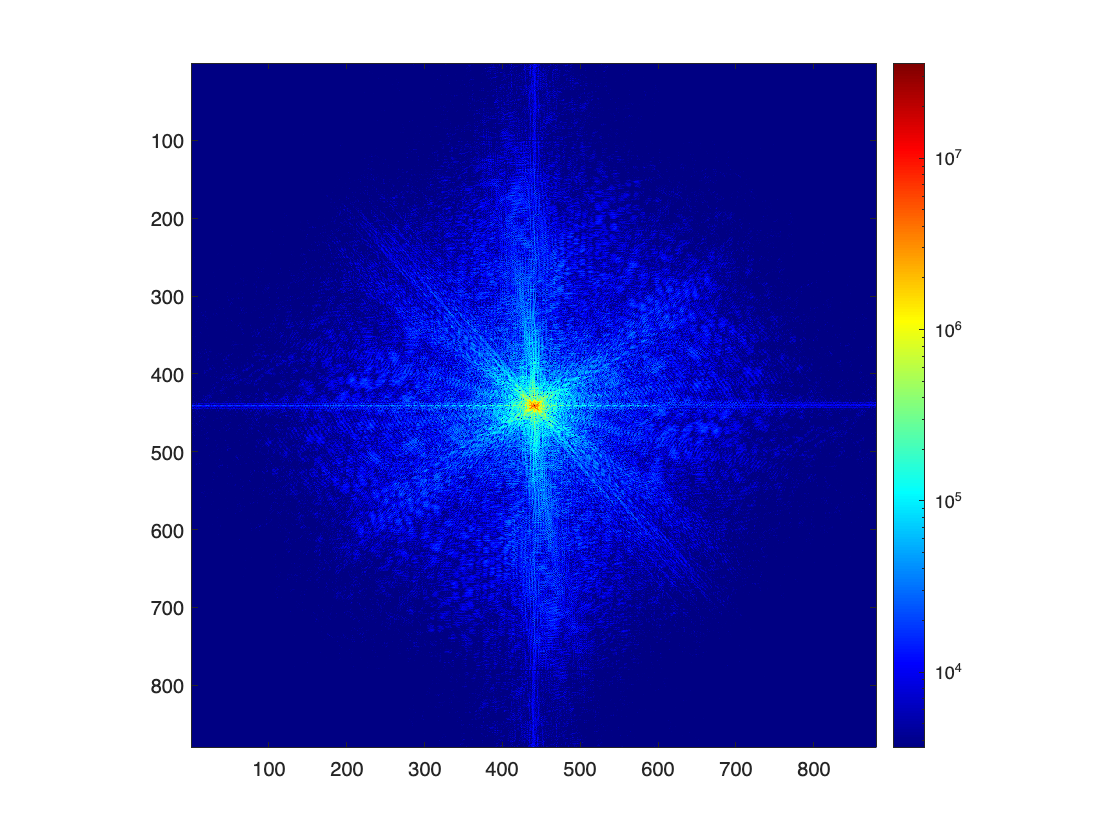

[Ic, Ikc] = pifft_conjugate_synthesis(Ip, 1, 600, 1, 780); 
figure(9); imagesc(abs(Ikc)); axis('square'); colormap('jet'); colorbar; set(gca, 'ColorScale', 'log');

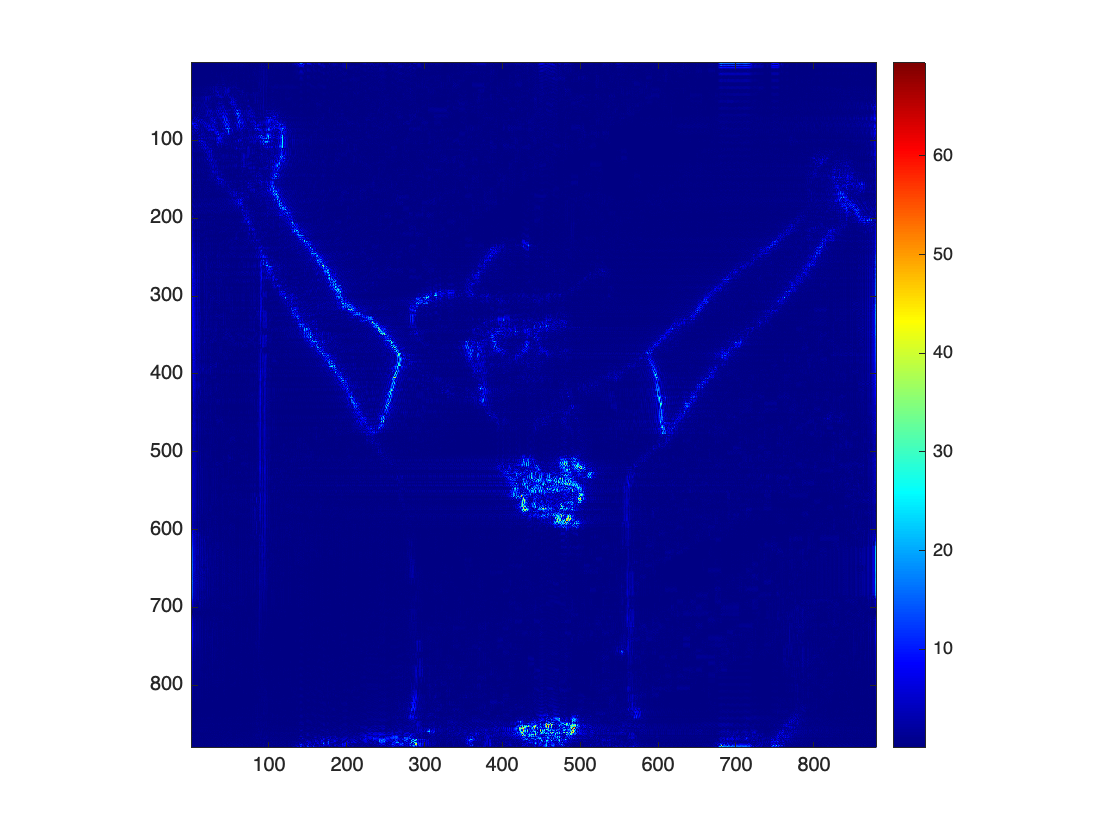

figure(10); imagesc(abs(abs(Ic)-double(I))); axis('square'); colormap('jet'); colorbar;

disp(immse(abs(Ic),double(I)));

    5.0187



## Homodyne Reconstruction

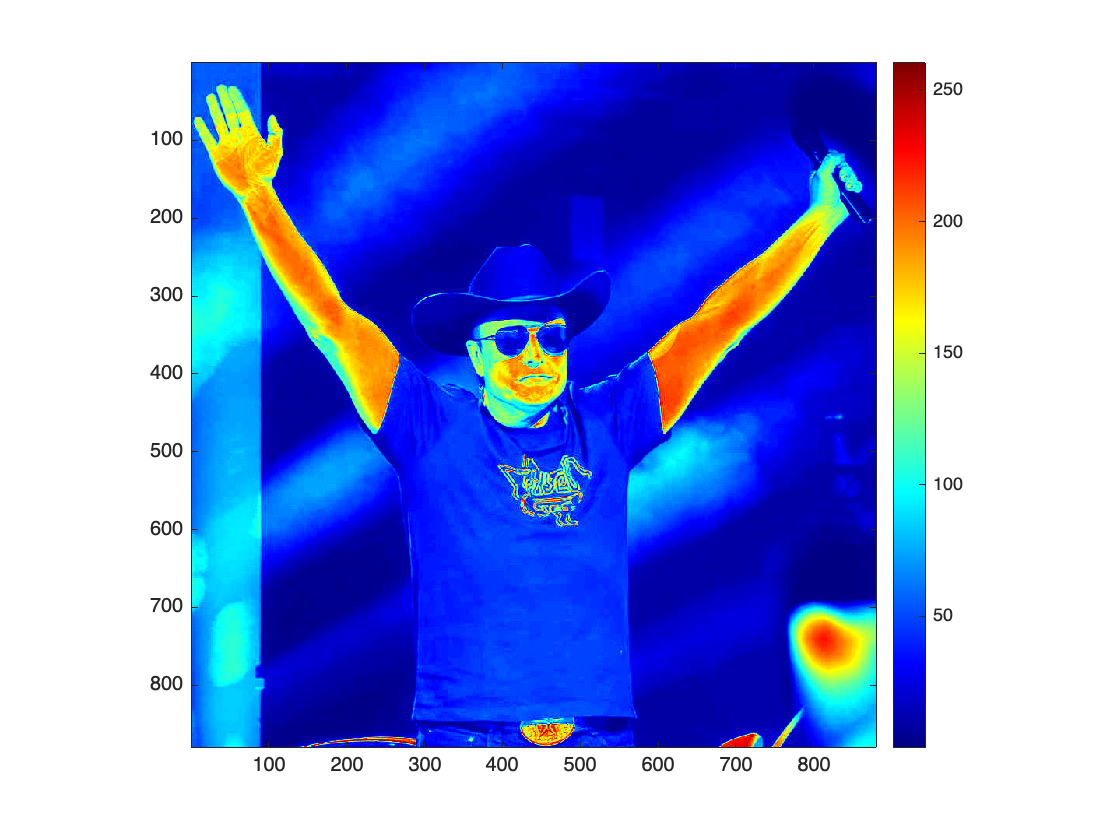

[Ih,Ihs,hW,Ihw,Ihfs,Ihfw] = pifft_homodyne_reconstruction(I_f, 1, 600, 1, 780, "step", true, 0.1); 
figure(12); imagesc(abs(Ihfw)); axis('square'); colormap('jet'); colorbar; set(gca, 'ColorScale', 'linear');

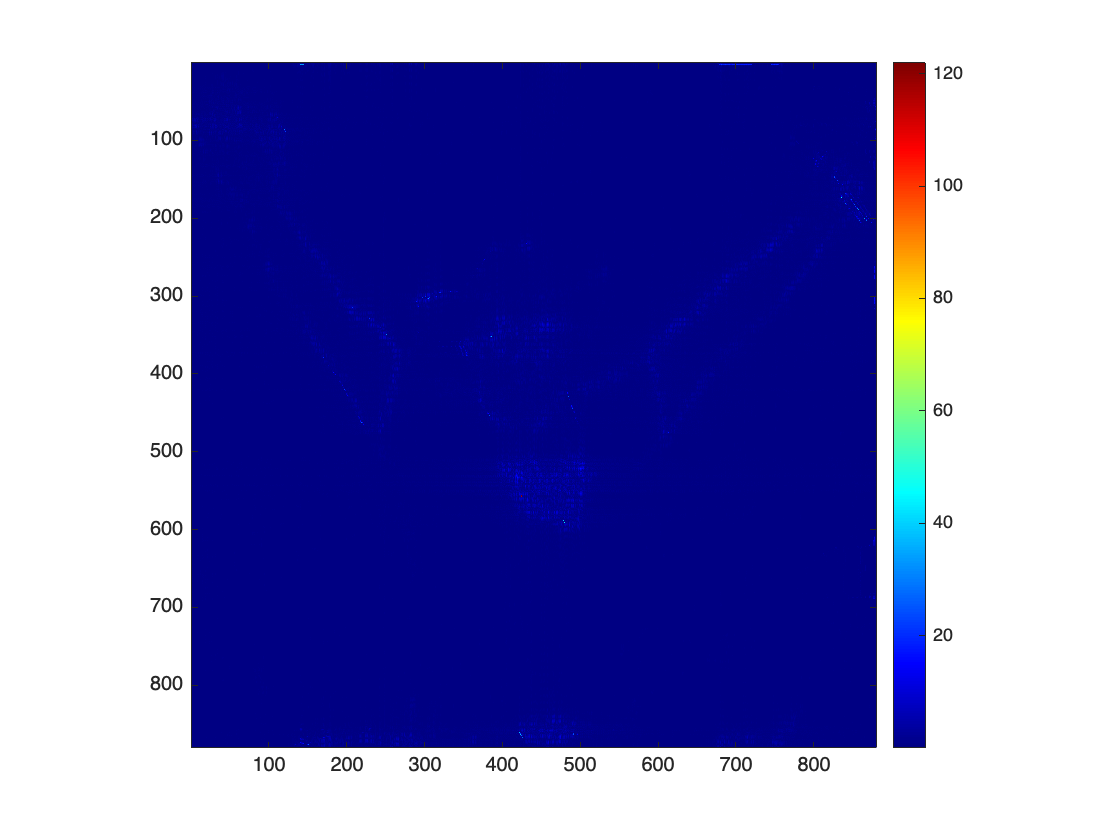

figure(11); imagesc(abs(real(Ih)-double(I))); axis('square'); colormap('jet'); colorbar;

disp(immse(real(Ih),double(I)));

    0.5531

